Create a simple signal with two frequencies

clear all, close all, clc
%% Create a simple signal with two frequencies
dt = .001;
t = 0:dt:1;
f = sin(2*pi*50*t) + sin(2*pi*120*t); % Sum of 2 frequencies

Add noise, use

2.5*randn(size(t));  

Compute the Fast Fourier Transform FFT, use the parameters

n = length(t);
fhat = fft(f,n);       % Compute the fast Fourier transform

What is fhat? Use

inverseFFT_fhat = ifft(?); % Inverse FFT

to obtain a function "inverseFFT_fhat". Compute the error between "f" and "inverseFFT_fhat". What does the error indicate about inverseFFT_fhat and f?

?

Now, compute power spectrum 

PSD = ?.*conj(?)/n; % Power spectrum (power per freq)

Use the PSD to filter out noise. Zero out all frequences with power larger than 100.

%% Use the PSD to filter out noise
indices = PSD>?; 
PSDclean = ?.*indices;  % Zero out all others
? = indices.*?;  % Zero out small Fourier coeffs. in Y
? = ifft(?); % Inverse FFT for filtered time signal

Plot

%% PLOTS
subplot(3,1,1)
plot(?,?,'r','LineWidth',1.2), hold on
plot(?,?,'k','LineWidth',1.5)
legend('Noisy','Clean')

subplot(3,1,2)
plot(?,?,'b','LineWidth',1.2)
axis([0 1 -10 10])
legend('Clean','Filtered')


Create x-axis of frequencies in Hz and plot the first half of freqs

freq = 1/(dt*n)*(0:n);
L = 1:floor(n/2);

Plot PSD and PSDclean

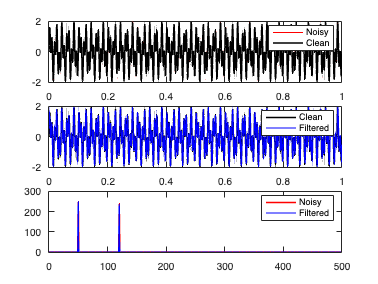

subplot(3,1,3)
plot(?(L),?(L),'r','LineWidth',1.5), hold on
plot(?(L),?(L),'-b','LineWidth',1.2)
legend('Noisy','Filtered')